# Example: Bouncing Ball

The code below gives a reachability analysis example for hybrid systems in CORA.

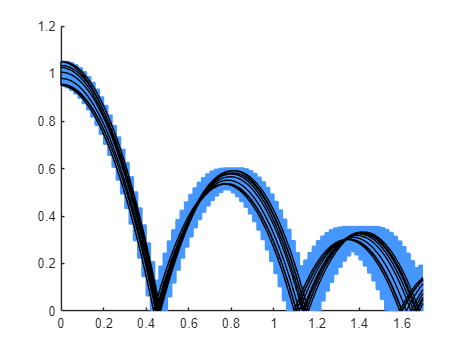

% Parameter ---------------------------------------------------------------

% problem description
params.R0 = zonotope([1;0],diag([0.05,0.05]));      % initial set
params.startLoc = 1;                                % initial location
params.tFinal = 1.7;                                % final time


% Reachability Options ----------------------------------------------------

% settings for continuous reachability 
options.timeStep = 0.02;
options.taylorTerms = 10;
options.zonotopeOrder = 20;

% settings for hybrid systems
options.guardIntersect = 'polytope';
options.enclose = {'box'}; 


% Hybrid Automaton --------------------------------------------------------

% continuous dynamics 
A = [0 1; 0 0];
B = [0; 0];
c = [0; -9.81];
linSys = linearSys('linearSys',A,B,c);

% system parameters
alpha = -0.75;                  % rebound factor

% invariant set 
inv = polytope([-1,0],0);

% guard sets
guard = polytope([0,1],0,[1,0],0);

% reset function
reset = linearReset([0, 0; 0, alpha],[],zeros(2,1));

% transitions
trans = transition(guard,reset,1);

% location object
loc = location('loc1',inv,trans,linSys); 

% hybrid automata
HA = hybridAutomaton(loc);


% Reachability Analysis ---------------------------------------------------

tic;
R = reach(HA,params,options);
tComp = toc;


% Simulation --------------------------------------------------------------

simRes = simulateRandom(HA,params); 


% Visualization -----------------------------------------------------------

figure; hold on;
useCORAcolors("CORA:contDynamics")

% plot reachable set
plotOverTime(R,1,'DisplayName','Reachable set');

% plot initial set
plotOverTime(R(1).R0,1,'HandleVisibility','off');

% plot simulated trajectories
plotOverTime(simRes,1,'DisplayName','Simulations');

xlim([0,1.7]);
ylim([0,1.2]);